# Module 2 Quiz

## Analyzing Videos

v = VideoReader("liquidVideo.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'liquidVideo.mp4'
            Path: 'D:\Mina\Document\Coursera\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 120
          Height: 216
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


#### Question 1

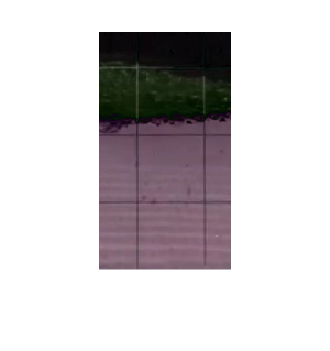

background = im2double(read(v, 1));
frame_175 = im2double(read(v, 175));
Diff_175 = abs(background - frame_175);
imshow(Diff_175)

#### Question 2

Grayscale binarization with Otsu's method

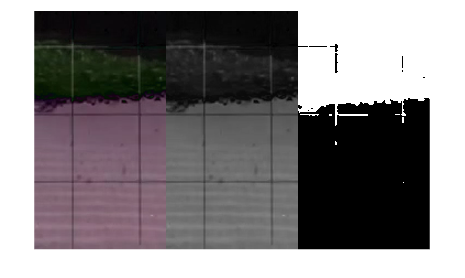

imgGray = im2gray(Diff_175);
imgOtus = imbinarize(imgGray);
montage({Diff_175, imgGray, ~imgOtus}, "Size", [1, 3])

(This method can work for frames in the middle of the video if your sensitivity is set properly, but for the frames at the beginning and end, this method will force a binarization of the image that no longer isolates the liquid because it is either not present or occupies the entire frame.)

#### Question 2

Grayscale binarization with a manual threshold value

% [~,effectiveness] = graythresh(Diff_175)

effectiveness = 0.8872

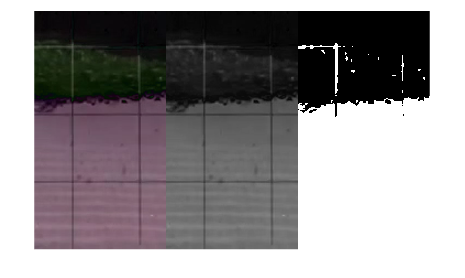

imgManual = imbinarize(imgGray, 0.2);
montage({Diff_175, imgGray, imgManual}, "Size", [1, 3])

(This is the ideal method because it will properly isolate the liquid even when it is not present or occupies the entire frame.)

#### Question 2

Grayscale binarization with adaptive thresholding

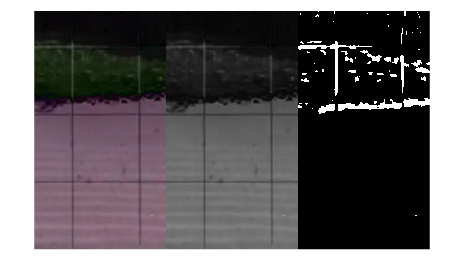

imgAdaptive = imbinarize(imgGray, "adaptive", "ForegroundPolarity", ...
    "bright", "Sensitivity", 0.3);
montage({Diff_175, imgGray, imgAdaptive}, "Size", [1, 3])

(This method can work for frames in the middle of the video if your sensitivity is set properly, but for the frames at the beginning and end, this method will force a binarization of the image that no longer isolates the liquid because it is either not present or occupies the entire frame.)

#### Question 2

Clustering

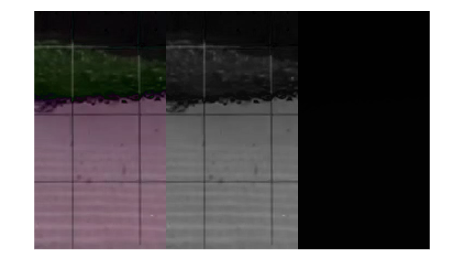

imgCluster = imsegkmeans(im2single(frame_175), 2);
montage({Diff_175, imgGray, imgCluster}, "Size", [1, 3])

#### Question 3

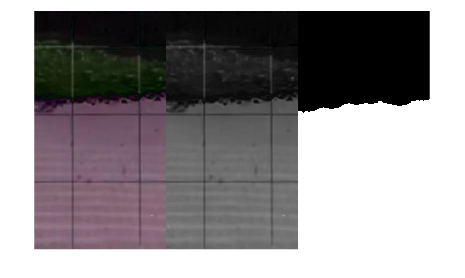

bw = liquidSegment(imgManual);

montage({Diff_175, imgGray, bw}, "Size", [1, 3])

#### Question 4

Liquid = sum(bw(:));
Empty = sum(~bw(:));

LiquidPercent = Liquid/(Liquid + Empty)

LiquidPercent = 0.6046

#### Question 5

vOut = VideoWriter("MyliquidBinary.mp4", "MPEG-4")

vOut =   VideoWriter

    General Properties:

       Filename:                 'MyliquidBinary.mp4'
       Path:                     'D:\Mina\Document\Coursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


vOut.FrameRate = v.FrameRate;

open(vOut);

for idx = 1:v.NumFrames
    
    frame = im2double(read(v, idx));
    Diff = abs(background - frame);
    
    Gray = im2gray(Diff);
    Manual = imbinarize(Gray, 0.2);

    BW = liquidSegment(Manual);
    
    img = imfuse(frame, BW, "montage");
    writeVideo(vOut, img);

end

close(vOut);

function BW = liquidSegment(X)

    radius = 11;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imopen(X, se);
    
    % Close mask with disk
    radius = 11;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imclose(BW, se);

end